# DC Microgrid Simulator

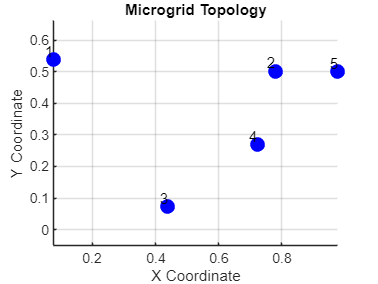

Coordinates of DGs:
    0.0763    0.5385
    0.7799    0.5011
    0.4384    0.0721
    0.7235    0.2684
    0.9780    0.4999

Adjacency Matrix:
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0

B_il Matrix:

MOSEK Version 10.1.25 (Build date: 2024-2-14 13:14:18)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 60              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 25              
  Matrix variables       : 10 (scalarized: 255)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear depende

clear all
close all
clc

rng(7)
% 
% numOfDGs = 6;
% threshold = 0.9;

numDGsRange = 5:6;  % Example range for number of DGs
thresholdRange = 0.1:0.1:1;  % Example range for threshold values
pScalarRange = 0.01:0.01:10;  % Example range for pScalar values
BarGamma = 5;  % Fixed value for gammaBar
isSoft = 1;    % Set to 1 to use soft constraint

% Call the function
evaluateDesigns(numDGsRange, thresholdRange, BarGamma, pScalarRange, isSoft);

## Generate a random physical topology

% Input: numOfDGs and physicalDistanceThreshold

% I should be able to change "numOfDGs" and "numOfLines" variables freely
% see https://en.wikipedia.org/wiki/Random_geometric_graph
% https://github.com/shiran27/NetworkedSystemAnalysisAndControl/blob/main/Network.m
% particularly look at the function: loadARandomNetwork

% Generate a topology randomly
% Generate numOfDGs number of random points in R^2 spase using rand(1,2)
% If two generated points are closer to each other than a predefined
% threshold, they are assumed as connected. 

% Final output: of this code is B=[B_il]_{i,l} matrix and the numOfLines
% plot the graph like in Fig 2.
% A = [A_ij]_{i,j} is the adgacency matrix of the DG-DG topology (N\times N)
[coords, A_ij, B_il] = generateMicrogridTopology(numOfDGs, threshold)

## Generate Random set of DGs

% Initial parameter values for DGs
R0 = 0.02;      % Resistance
L0 = 0.01;      % Inductance
C0 = 0.0022;    % Capacitance
RL0 = 0.3;      % Load Resistance
Y0 = 1/RL0;     % Load Conductance



for i = 1:1:numOfDGs
    DG{i} = GenerateDG(R0,L0,C0,RL0,coords(i,:));
    
    [PVal, KVal, LVal, nuVal, rhoVal, status] = ComputePassivityForDGs(DG{i});
end


## Generate Random Set of Lines

% Initial parameter values for Lines
Rl0 = 0.02;     % Line Resistance
Ll0 = 0.01;     % Line Inductance

numOfLines = size(B_il,2);

for l = 1:1:numOfLines
    Line{l} = GenerateLine(Rl0,Ll0);
    [PBarVal, nuBarVal, rhoBarVal, status] = ComputePassivityForLines(Line{l});
end

Clear variables unrelated

 clearvars -EXCEPT DG Line numOfDGs numOfLines A_ij B_il 
 % global DG Line B_il A_ij

## Co-Design Process

parameters


BarGamma = 1;    % Fixed value for gammaBar
isSoft = 1; % Set to 1 to avoid the hard graph constraint

pScalar = 1/(numOfDGs+numOfLines)

piVals = pScalar*ones(1,numOfDGs);
plVals = pScalar*ones(1,numOfLines);

## 1. Centralized Local Controller Design

[DG,Line,statusLocalController] = centralizedLocalControlDesign(DG,Line,B_il,BarGamma,piVals,plVals) % topologyMetrics may be the B matrix 
DG{1}
% Inside the function, youneed to solve the LMI problem in (66) and add
% local passivity information and local controller information to the DG
% and Line variables. 

## 2. Global Controller Design

[DG,Line,statusGlobalController,gammaTildeVal] = globalControlDesign(DG,Line,A_ij,B_il,BarGamma,isSoft)
DG{1}.K{1,1}
DG{1}.K{1,2}

Optimize pVals (Method 1: Qucik and Dirty, Run this in a seperate .m file - to get faster result) 

% See the 'OptimizepValsMethod1.m' file. 

Optimize pVals (Method 2: Use Matlab 'fmincon')

% [piVals, plVals] = optimizeCodesignParameters()